# **MATLAB**

MATLAB (MATrix LABoratory) is a high-level programming language and interactive environment for algorithm development, data visualization, data analysis, and numeric computation. Core strengths of the system include rapid development, powerful built-in functionality and extensive application-specific functionality provided by both official toolboxes and user-contributed code.

MATLAB contains several different parts:

- **Desktop Tools and Development Environment** **-** This part of MATLAB is the set of tools and facilities that help you use and become more productive with MATLAB functions and files. Many of these tools are graphical user interfaces. It includes: the MATLAB desktop and Command Window, an editor and debugger, a code analyzer, and browsers for viewing help, the Workspace, and folders.

- **Mathematical Function Library -** This library is a vast collection of computational algorithms ranging from elementary functions, like sum, sine, cosine, and complex arithmetic, to more sophisticated functions like matrix inverse, matrix eigenvalues, and fast Fourier transforms.

- **The Language -** The MATLAB language is a high-level matrix/array language with control flow statements, functions, data structures, input/output, and object-oriented programming features. It allows both "programming in the small" to rapidly create quick programs you do not intend to reuse. You can also do "programming in the large" to create complex application programs intended for reuse.

- **Graphics -** MATLAB has extensive facilities for displaying vectors and matrices as graphs, as well as annotating and printing these graphs. It includes high-level functions for two-dimensional and three-dimensional data visualization, image processing, animation, and presentation graphics. It also includes low-level functions that allow you to fully customize the appearance of graphics as well as to build complete graphical user interfaces on your MATLAB applications.

- **External Interfaces -** The external interfaces library allows you to write C and Fortran programs that interact with MATLAB. It includes facilities for calling routines from MATLAB (dynamic linking), for calling MATLAB as a computational engine, and for reading and writing MAT-files.

# **References**

**A MATLAB Tutorial - Ed Overman, Department of Mathematics, The Ohio State University**

**Introduction to MATLAB for engineering students, David Houcque, Northwestern University**

**MATLAB, An Introduction, IT Services, University of Oxford**

# **Summary**

- **Desktop tools and development environment**

- **Definitions: Matrices and Vectors**

- **Matlab data types**

- **Scalar calculations**

- **Variables**

- **Script M-files**

- **Functions**

- **Vectors**

- **Matrices**

- **Basic plotting**

# **Desktop Tools and Development Environment**

demo
help plot
doc plot
lookfor plot
who
whos
clc

# 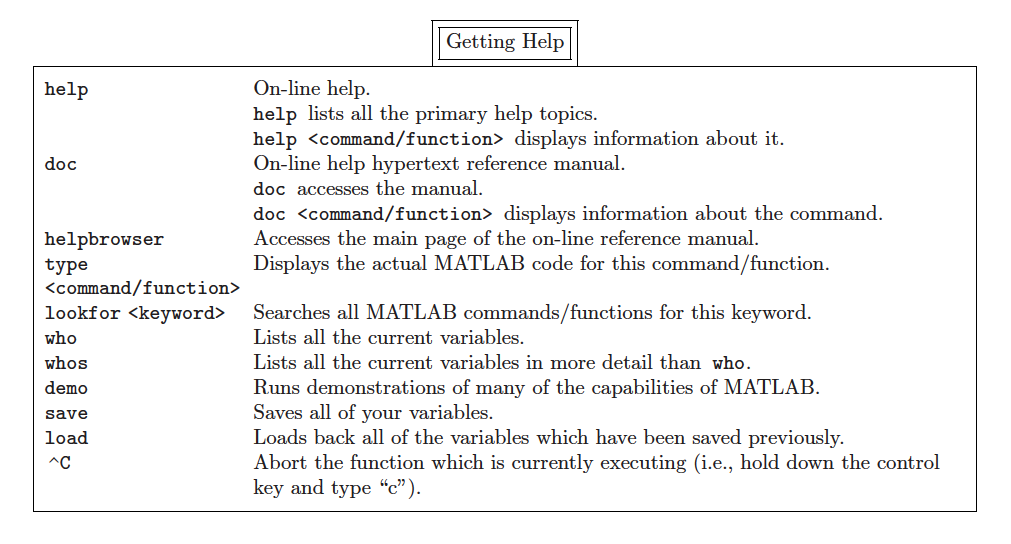

# **Definitions: Matrices and Vectors**

- `The most basic MATLAB data structure is the matrix: a two-dimensional, rectangular structure capable of storing multiple elements of data in an easily accessible format.`

- `The elements of a matrix must all be of the same data type (numeric, character, logical etc.), but here we will focus on numeric matrices.`

- `MATLAB uses two-dimensional matrices to store single elements and linear series of elements as well. In these cases, the dimensions are 1-by-1 and 1-by-N (or N-by-1) respectively. For numeric data, special meaning is sometimes attached to 1-by-1 matrices, which are scalars, and to matrices with only one row or column, which are vectors.`

- `MATLAB also supports data structures that have more than two dimensions. These data structures are referred to as multidimensional arrays, and indeed the matrix is really a special case of an n-dimension array, with n=2.`

# **MatLab data types**

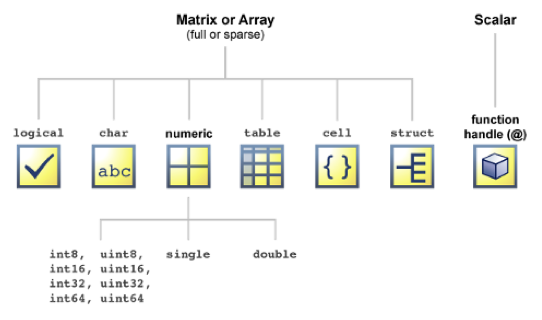

[http://www.mathworks.com/help/matlab/matlab_prog/fundamental-matlab-classes.html](http://www.mathworks.com/help/matlab/matlab_prog/fundamental-matlab-classes.html)

# **Scalar Calculations**

## Simple Arithmetical Operations

MATLAB can be used as a scientific calculator:

14*2+2/2

2^0
2^1
2^20

2*10^-1
2e-1
2E-1
2.e-1
2.E-1

e-1
1e-1


# **Variables**

x = 2
x
x;
fx = 3*x^6 - 17*x^3+79
x = 2^(1/3); fx = 3*x^6 - 17*x^3 + 79; g = 3/fx;
x = 2^(1/3), fx = 3*x^6 - 17*x^3 + 79, g = 3/fx
x = x+5
x
clear

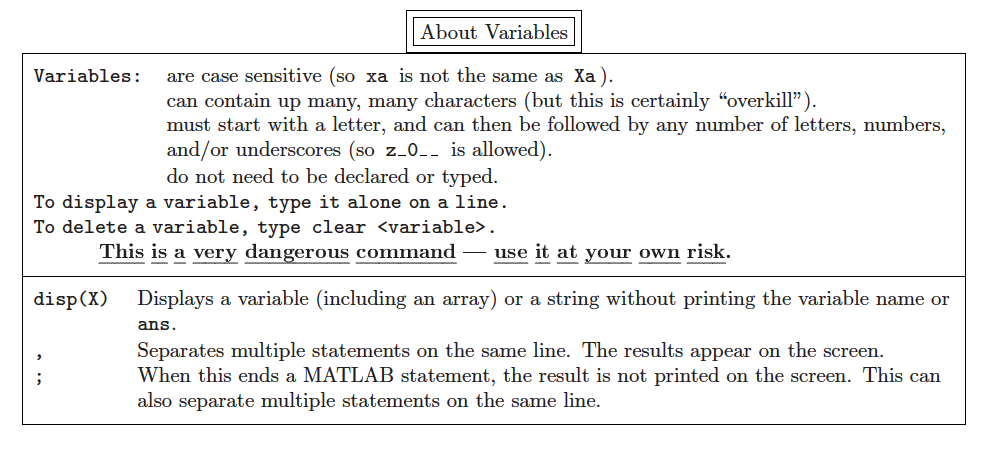

There are reserved names/words, called keywords:

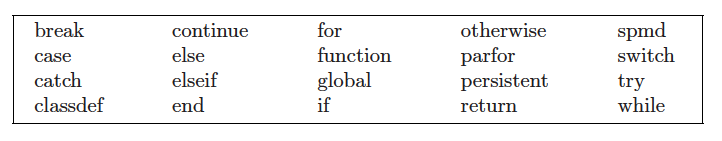

...as well as predefined variables:

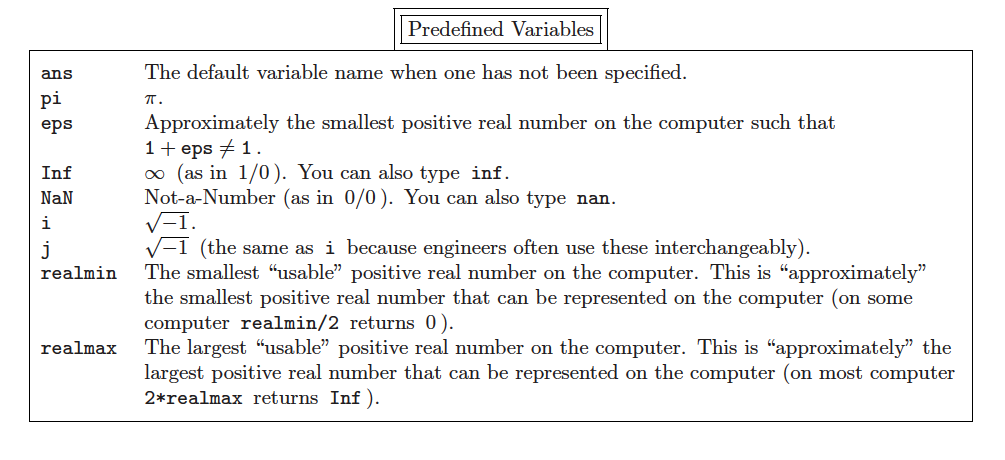

a=1/3
format long
a
format short
a

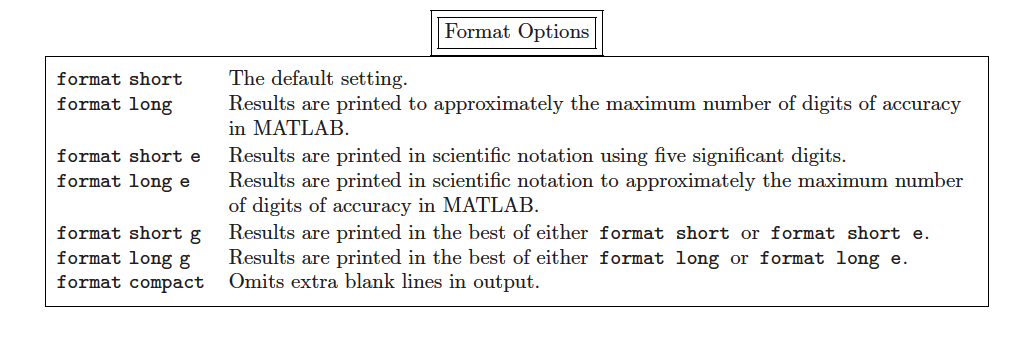

clear

Undefined function or variable 'fg'.

who
diary
a=5
b=10
c=a*b
diary off
save a b
clear
who
save('vars','a','b')
clear
who
load('vars')


# **Script M-files**

edit workshop.m
workshop

- The name of the file includes the extension ".m", i.e., "<file name>.m", but you execute it in MATLAB by typing <file name>, i.e., without the extension.

- The file name can consist of (almost any number of) letters (lowercase and/or uppercase), numbers, and underscores, i.e. "_".

- The first character must be a letter.

- Spaces are not allowed.

- Make sure your file name is not the same as one of MATLAB's commands/functions.

type workshop

# **Functions**

Functions are programs (or routines) that accept input arguments and return output arguments. Each M-file function (or function or M-file for short) has its own area of workspace, separated from the MATLAB base workspace.

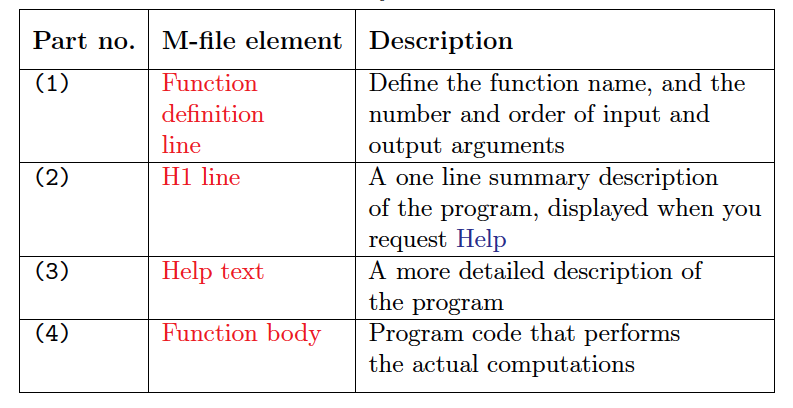

**function [outputs] = function_name(inputs)**

**    body**

**end**

**Examples of headers:**

-     function C=FtoC(F)

-     function area=TrapArea(a,b,h)

-     function [h,d]=motion(v,angle)

% Define a function that calculates the factorial of a number n

## **Scripts vs Functions**

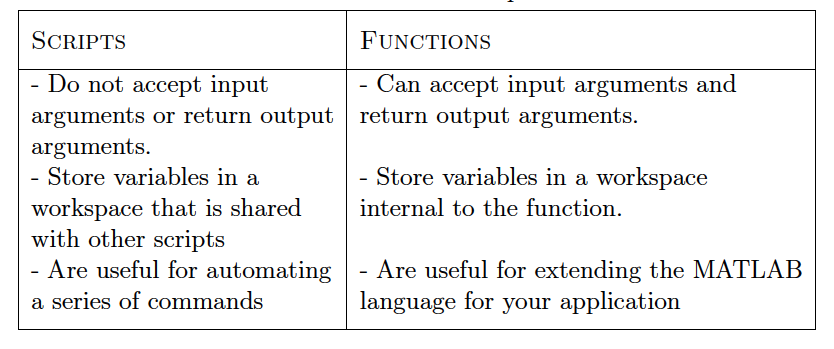

# **Vectors**


clear
who
x=[3 2 4 7 5]
x=[3,2,4,7,5]
y=[3;2;4;7;5]

x(1)
x(0)
x(6)
x(3)

y=1:5
y=1:5'
y=(1:5)'

x=1:5
x=1:2:10

x1 = linspace(1,10,5);
y1=x1(3:4)
y1(2)=3
x1
y1(5)=4

x=[3 5]
x=[x x]

x=1:5
x+x
x=x+x

x=1:5
x=x*0.5

y=1:5
x+y

x*y
x.*y
x*y'

x=10:-2:0
x=7:4

x=1:10;
max(x)
min(x)
sum(x)
prod(x)
mean(x)
std(x)

x=[1 23 5 17 8 3]
x<4
x(x<4)

x=[1 2 3]
y=[2 3 4]


# **Matrices**


clear
who
[7 -2 +5], [7 - 2 + 5], [7, - 2, +5]

A = [6 3 2 8; 5 1 3 7; 1, 6, 7, 2;4,5,4,1]
B = [6 3 2 8; 5 1 3]
ones(2,5)
zeros(2,2)
rand(2,2)

A = [1 2;3 4]
B = [5 6;7 8]

A+B
A-B
C=[A,B]
D=[A;B]

B = [5 6;7 8;9 10]
C=[A,B]
D=[A;B]

A = [6 3 2 8; 5 1 3 7; 1, 6, 7, 2;4,5,4,1]
A(3,2)
A(7)
linearindex = sub2ind(size(A),3,2)
[X,Y] = ind2sub(size(A),5)

A(2,1:3)
A(1:3:16)
A(2:3,1:3)

A(2,2:end)
A(2,:)
A([1,4,9])

L = A<5
A(L)
A(A<5)
A(L) = 0

size(A)
length(A)
numel(A)

islogical(A)
isnumeric(A)

isvector(A)
isscalar(A)
ismatrix(A)
isempty(A)

F = [1,2,3;4,5,6];
F(1,5)
F(1,5)=3

F = [1,2,3;4,5,6];
F(1:2,5:6) = 8
F(:,6) = []

F = [1,2,3;4,5,6]
transpose(F)
reshape(F,3,2)

A = [6 3 2 8; 5 1 3 7; 1, 6, 7, 2;4,5,4,1]
sort(A,1)
sort(A,2)

sort(A,2,'descend')
sortrows(A,2)

max(A)
max(A,[],2)
[y,I]=max(A,[],2)

mean(A,1)
mean(A,2)

sum(A(1,:))/length(A(1,:))
sum(A(2,:))/length(A(2,:))

**There are many more operations on matrices. Here are a few of them:**

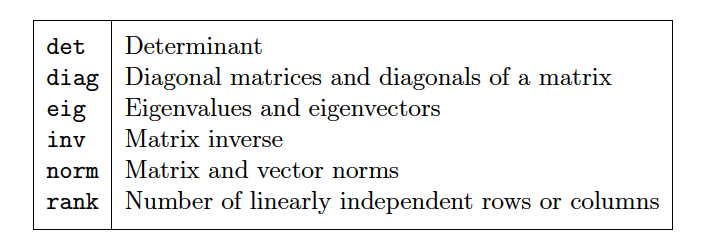

# **Basic plotting**

The basic MATLAB graphing procedure, for example in 2D, is to take a vector of x-coordinates, x = (x1; ... ; xN), and a vector of y-coordinates, y = (y1; ... ; yN), locate the points (xi; yi), with i = 1; 2; ... ; n and then join them by straight lines. You need to prepare x and y in an identical array form; namely, x and y are both row arrays or column arrays of the same length.

clear

x = 0:pi/10:2*pi;
y1 = 2*cos(x);
y2 = cos(x);
y3 = 0.5*cos(x);
plot(x,y1,'--rs',x,y2,'-gd',x,y3,':bo',...
       'LineWidth',2,...
       'MarkerEdgeColor','k',...
       'MarkerSize',10)
   
xlabel('0 \leq x \leq 2\pi')
ylabel('Cosine functions')
legend('2*cos(x)','cos(x)','0.5*cos(x)')
title('Typical example of multiple plots')
axis([0 2*pi -3 3])